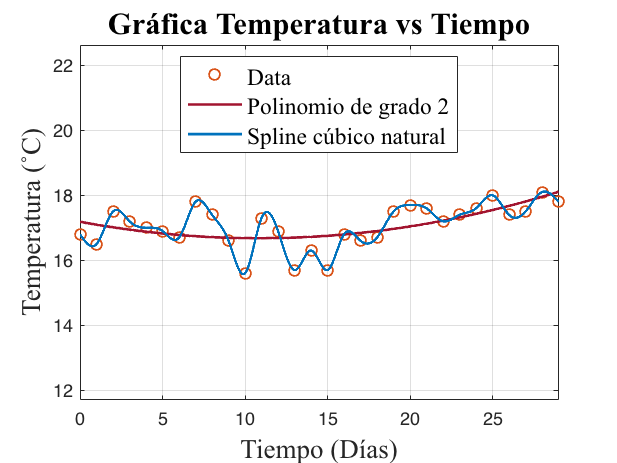

hora = input("Ingresa la hora del día a analizar (0-23): ");
grado = input("Ingresa el grado del polinomio aproximante: ");

grafica(hora+1, grado);

function [] = grafica(hora, grado)
    
    T = readmatrix('data.csv','Range','C12:C730')';
    T = T(hora:24:end);
    
    t = (0:1:length(T)-1);
    
    P = polyfit(t, T, grado);
    tt = linspace(0, length(t)-1, 1000);
    Pt = polyval(P, tt);
    
    % Gráfica de la data
    plot(t, T, 'o', "Color", '#D95319', "LineWidth", 1)
    grid on, hold on;
    
    % Gráfica del polinomio mínimos cuadrados
    plot(tt, Pt, "Color", '#A2142F', "LineWidth", 1.5)
    
    % Gráfica del Spline Cúbico Natural
    spline_cubico_natural(t, T, '#0072BD');
    hold off;
    
    % axis([min(t) max(t) min(T)-0.2 max(T)+0.2])
    xlim([min(t)     max(t)    ])
    ylim([3/4*min(T) 5/4*max(T)])
    
    legend(...
        "Data", ...
        "Polinomio de grado " + int2str(grado), ...
        "Spline cúbico natural", ...
        "Location", "best", ...
        "FontSize", 13, ...
        "FontName", "Times New Roman")
    
    xlabel(...
        "Tiempo (Días)", ...
        "FontSize", 15, "FontName", "Times New Roman")
    
    ylabel(...
        "Temperatura (˚C)", ...
        "FontSize", 15, "FontName", "Times New Roman" )
    
    title(...
        "Gráfica Temperatura vs Tiempo", ...
        "FontSize", 17, "FontName", "Times New Roman")
    
end